# Lake inflow modelation

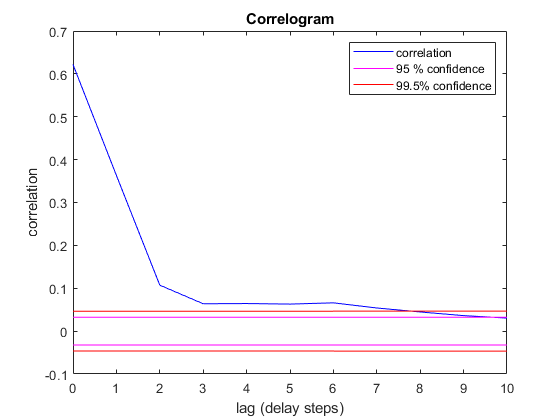

addpath('utils/')
data = load("data\dataPQ_1980_1997.txt");
T = 365;
% Training dataset
years_tr = 10;
u_tr = data(1:T*years_tr,1);  % Input
x_tr = data(1:T*years_tr,2);  % Output
% Validation dataset
u_val = data(T*years_tr+1:end,1);
x_val = data(T*years_tr+1:end,2);

figure; correlogram(x_tr,u_tr,10)

## 0. Data Normalization

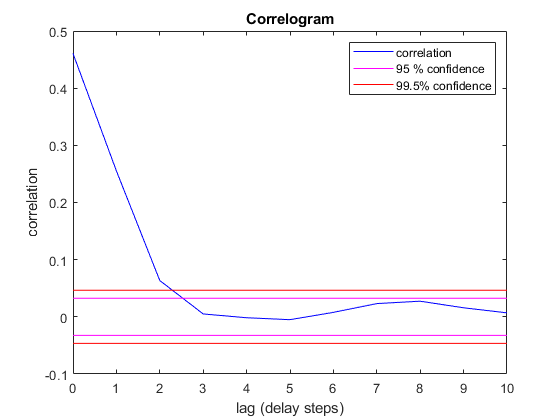

f = 5;
[x_norm, mean_x, sigma_x] = deseasonalize(x_tr, T, f);
[u_norm, mean_u, sigma_u] = deseasonalize(u_tr, T, f);

[x_val_norm, mean_x_val, sigma_x_val] = deseasonalize(x_val, T, f);
[u_val_norm, mean_u_val, sigma_u_val] = deseasonalize(u_val, T, f);

figure; correlogram(x_norm, u_norm, 10)

## AR(1)

y_ar = x_norm(2:end);
M_ar = x_norm(1:end-1);
theta_ar = M_ar\y_ar

theta_ar = 0.7182

x_norm_ar = [x_norm(1); M_ar*theta_ar];
x_ar = x_norm_ar .* sigma_x + mean_x;
r2_ar = r2_performance(x_tr, x_ar, mean_x)

r2_ar = 0.5077

### Validation

M_ar_val = x_val_norm(1:end-1);
x_val_norm_ar = [x_val_norm(1); M_ar_val*theta_ar];
x_val_ar = x_val_norm_ar .* sigma_x_val + mean_x_val;
r2_ar_val = r2_performance(x_val, x_val_ar, mean_x_val)

r2_ar_val = 0.5624

## Proper model ARX(1,1)

y_prop = x_norm(2:end);
M_prop = [x_norm(1:end-1), u_norm(1:end-1)];
theta_prop = M_prop\y_prop

theta_prop =     0.7437
   -0.0548


x_norm_arx_prop = [x_norm(1); M_prop*theta_prop];
x_arx_prop = x_norm_arx_prop .* sigma_x + mean_x;
r2_prop = r2_performance(x_tr, x_arx_prop, mean_x)

r2_prop = 0.5114

### Validation

M_prop_val = [x_val_norm(1:end-1), u_val_norm(1:end-1)];
x_val_norm_arx_prop = [x_val_norm(1); M_prop_val*theta_prop];
x_val_arx_prop = x_val_norm_arx_prop .* sigma_x_val + mean_x_val;
r2_prop_val = r2_performance(x_val, x_val_arx_prop, mean_x_val)

r2_prop_val = 0.5684

## Improper model ARX(1,1)

y_improp = x_norm(2:end);
M_improp = [x_norm(1:end-1), u_norm(2:end)];
theta_improp = M_improp\y_improp

theta_improp =     0.6425
    0.2948


x_norm_arx_improp = [x_norm(1); M_improp*theta_improp];
x_arx_improp = x_norm_arx_improp .* sigma_x + mean_x;
r2_improp = r2_performance(x_tr, x_arx_improp, mean_x)

r2_improp = 0.6983

### Validation

M_improp_val = [x_val_norm(1:end-1), u_val_norm(2:end)];
x_val_norm_arx_improp = [x_val_norm(1); M_improp_val*theta_improp];
x_val_arx_improp = x_val_norm_arx_improp .* sigma_x_val + mean_x_val;
r2_improp_val = r2_performance(x_val, x_val_arx_improp, mean_x_val)

r2_improp_val = 0.7304

## Proper ANN

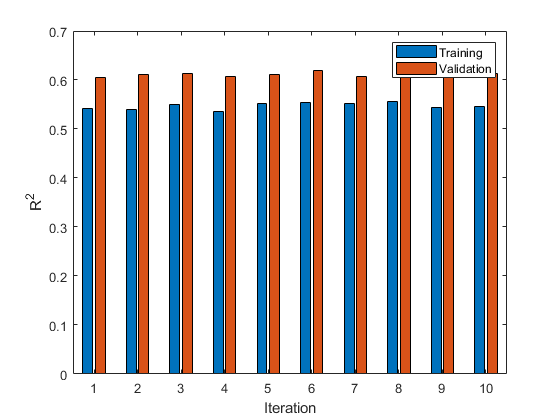

% Train dataset
x_ann = [x_norm(1:end-1), u_norm(1:end-1)]';
y_ann = x_norm(2:end)';
% Validation dataset
x_ann_val = [x_val_norm(1:end-1) u_val_norm(1:end-1)]';

N_runs = 10;
r2_ann_prop = zeros(N_runs, 1);
r2_ann_prop_val = zeros(N_runs, 1);
for i = 1:N_runs
    % ANN Train
    ann_prop_i = feedforwardnet(3);
    ann_prop_i = train(ann_prop_i,x_ann,y_ann);
    
    % view(ann_prop)
    y = ann_prop_i(x_ann);
    y_ann_prop = [x_norm(1); y'];
    x_ann_prop = y_ann_prop .* sigma_x + mean_x;
    
    r2_ann_prop(i) = r2_performance(x_tr, x_ann_prop, mean_x);
    
    % Validation
    y = ann_prop_i(x_ann_val);
    y_ann_prop_val = [x_val_norm(1); y'];
    x_ann_prop_val = y_ann_prop_val .* sigma_x_val + mean_x_val;
    
    r2_ann_prop_val(i) = r2_performance(x_val, x_ann_prop_val, mean_x_val);
    
    if r2_ann_prop_val(i) >= max(r2_ann_prop_val)
        ann_prop = ann_prop_i; % Optimal ANN wrt validation dataset
    end
    
end

figure; 
h = bar([r2_ann_prop, r2_ann_prop_val]);
set(h, {'DisplayName'}, {'Training','Validation'}')
xlabel('Iteration');ylabel('R^2');
legend()

## Improper ANN

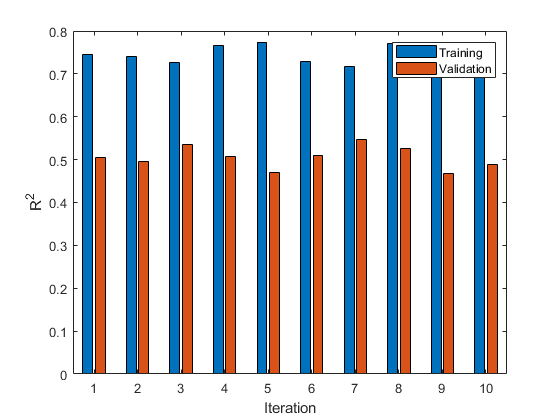

% Train dataset
x_ann = [x_norm(1:end-1), u_norm(2:end)]';
y_ann = x_norm(2:end)';
% Validation dataset
x_ann_val = [x_val_norm(1:end-1) u_val_norm(1:end-1)]';

N_runs = 10;
r2_ann_improp = zeros(N_runs, 1);
r2_ann_improp_val = zeros(N_runs, 1);
for i = 1:N_runs
    % ANN Train
    ann_improp_i = feedforwardnet(3);
    ann_improp_i = train(ann_improp_i,x_ann,y_ann);
    
    % view(ann_prop)
    y = ann_improp_i(x_ann);
    y_ann_improp = [x_norm(1); y'];
    x_ann_improp = y_ann_improp .* sigma_x + mean_x;
    
    r2_ann_improp(i) = r2_performance(x_tr, x_ann_improp, mean_x);
    
    % Validation
    y = ann_improp_i(x_ann_val);
    y_ann_improp_val = [x_val_norm(1); y'];
    x_ann_improp_val = y_ann_improp_val .* sigma_x_val + mean_x_val;
    
    r2_ann_improp_val(i) = r2_performance(x_val, x_ann_improp_val, mean_x_val);
    
    if r2_ann_improp_val(i) >= max(r2_ann_improp_val)
        ann_improp = ann_improp_i; % Optimal ANN wrt validation dataset
    end
    
end

figure; 
h = bar([r2_ann_improp, r2_ann_improp_val]);
set(h, {'DisplayName'}, {'Training','Validation'}')
xlabel('Iteration');ylabel('R^2');
legend()

## Classification and Regression Tree - CART

% x_cart = [x_norm(1:end-1), u_norm(1:end-1)];
% y_cart = x_norm(2:end);
% 

### Initial test to check how does it work...

% x_cart_test = x_cart(1:100,:);
% y_cart_test = y_cart(1:100);
% T = fitrtree(x_cart_test, y_cart_test);
% view(T, 'mode', 'graph')

Some stats...

% T.NumNodes
% figure
% subplot(311); plot( T.NodeSize ); title('node size'); % number of samples per node
% subplot(312); plot( T.NodeMean ); title('node mean'); % mean samples in each node
% subplot(313); plot( T.NodeError ); title('node error'); % node error

Performance test

% y_cart_predict = predict(T, x_cart_test);
% figure;
% plot([y_cart_test, y_cart_predict], '.-');
% legend('Observation','CART')

Controlling the leaf size

% T1 = fitrtree(x_cart_test, y_cart_test, 'MinLeafSize',10);
% view(T1, 'mode', 'graph')
% T1.NumNodes
% figure
% subplot(311); plot( T1.NodeSize ); title('node size'); % number of samples per node
% subplot(312); plot( T1.NodeMean ); title('node mean'); % mean samples in each node
% subplot(313); plot( T1.NodeError ); title('node error'); % node error

Performance test

% y_cart_predict_1 = predict(T1, x_cart_test);
% figure;
% plot([y_cart_test, y_cart_predict_1], '.-');
% legend('Observation','CART')

### Inflow model with CART

Iterate to find the best leaf size wrt to validation error

x_cart_val = [x_val_norm(1:end-1), u_val_norm(1:end-1)];
y_cart_val = x_val_norm(2:end);
    
max_leaf_size = 200;
r2_cart = zeros(max_leaf_size,1);
r2_cart_val = zeros(max_leaf_size,1);

for i = 1:max_leaf_size
    T_i = fitrtree(x_cart, y_cart,'MinLeafSize',i);
    % view(T, 'mode', 'graph');
    y_cart_predict = predict(T_i, x_cart);
    y_cart_predict = [x(1); y_cart_predict];
    x_cart_predict = y_cart_predict .* sigma_x + mean_x;
    r2_cart(i) = r2_performance(x_tr, x_cart_predict, mean_x);

### Validation

    y_cart_predict_val = predict(T_i, x_cart_val);
    y_cart_predict_val = [x_val_norm(1); y_cart_predict_val];
    x_cart_predict_val = y_cart_predict_val .* sigma_x_val + mean_x_val;
    r2_cart_val(i) = r2_performance(x_val, x_cart_predict_val, mean_x_val);
    
    if r2_cart_val(i) >= max(r2_cart_val)
        T_opt = T_i; % Optimal ANN wrt validation dataset
    end 
end

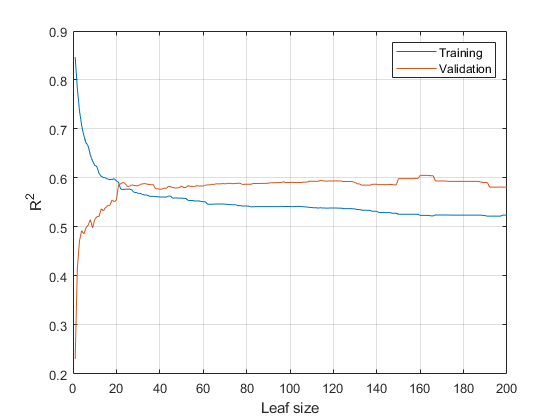

plot([r2_cart, r2_cart_val])
legend('Training','Validation')
xlabel('Leaf size');ylabel('R^2');
grid on

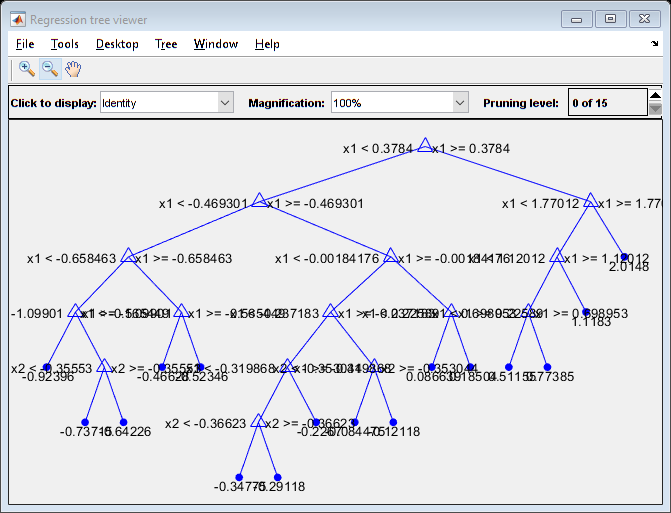

view(T_opt,'mode','graph')

T_opt.NumNodes

ans = 31

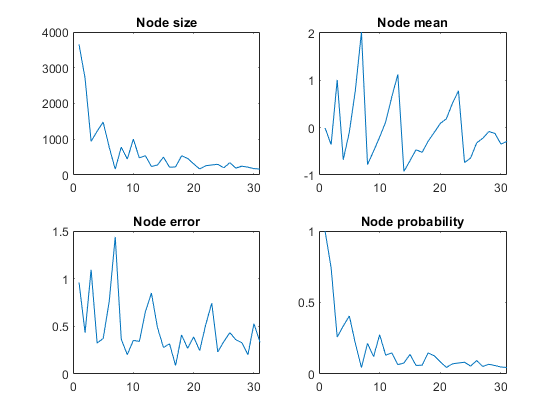

figure
subplot(2,2,1); plot( T_opt.NodeSize ); title('Node size'); % number of samples per node
subplot(2,2,2); plot( T_opt.NodeMean ); title('Node mean'); % mean samples in each node
subplot(2,2,3); plot( T_opt.NodeError ); title('Node error'); % node error
subplot(2,2,4); plot( T_opt.NodeProbability); title('Node probability')

Performance test

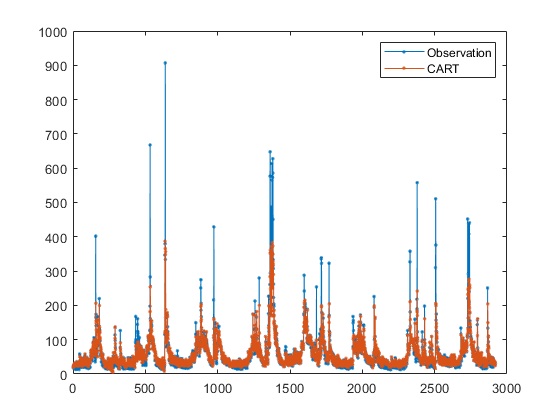

y_cart_predict_val = predict(T_i, x_cart_val);
y_cart_predict_val = [x_val_norm(1); y_cart_predict_val];
x_cart_predict_val = y_cart_predict_val .* sigma_x_val + mean_x_val;
figure;
plot([x_val, x_cart_predict_val], '.-');
legend('Observation','CART')

|======================================================================================|
| Iter | Eval   | Objective:  | Objective   | BestSoFar   | BestSoFar   |  MinLeafSize |
|      | result | log(1+loss) | runtime     | (observed)  | (estim.)    |              |
|======================================================================================|
|    1 | Best   |     0.38151 |    0.063954 |     0.38151 |     0.38151 |           84 |


|    2 | Accept |     0.51788 |     0.18072 |     0.38151 |     0.39026 |            2 |


|    3 | Accept |     0.44343 |    0.099335 |     0.38151 |     0.38161 |          792 |


|    4 | Accept |     0.42063 |      0.1534 |     0.38151 |     0.38235 |           12 |


|    5 | Best   |     0.38087 |    0.058629 |     0.38087 |     0.38098 |           93 |


|    6 | Accept |     0.38543 |    0.076189 |     0.38087 |     0.38111 |          140 |


|    7 | Accept |     0.38184 |    0.080665 |     0.38087 |     0.38121 |           70 |


|    8 | Accept |     0.38114 |    0.059066 |     0.38087 |     0.38119 |           86 |


|    9 | Accept |      0.3814 |      0.1109 |     0.38087 |     0.38123 |           87 |


|   10 | Accept |      0.6732 |     0.20527 |     0.38087 |     0.38121 |         1823 |


|   11 | Accept |     0.40217 |     0.11843 |     0.38087 |     0.38123 |          358 |


|   12 | Accept |     0.39527 |     0.06324 |     0.38087 |     0.38121 |           32 |


|   13 | Accept |      0.3835 |     0.05954 |     0.38087 |     0.38122 |           52 |


|   14 | Accept |     0.38169 |    0.063486 |     0.38087 |     0.38125 |          103 |


|   15 | Accept |     0.38087 |    0.066158 |     0.38087 |     0.38116 |           93 |


|   16 | Accept |     0.55919 |     0.21902 |     0.38087 |     0.38116 |            1 |


|   17 | Accept |     0.46485 |     0.14864 |     0.38087 |     0.38119 |            5 |


|   18 | Accept |     0.39499 |    0.069105 |     0.38087 |     0.38118 |          226 |


|   19 | Accept |     0.40372 |    0.069466 |     0.38087 |     0.38118 |           20 |


|   20 | Accept |     0.43024 |    0.062265 |     0.38087 |     0.38109 |          526 |


|======================================================================================|
| Iter | Eval   | Objective:  | Objective   | BestSoFar   | BestSoFar   |  MinLeafSize |
|      | result | log(1+loss) | runtime     | (observed)  | (estim.)    |              |
|======================================================================================|
|   21 | Best   |     0.38055 |    0.052445 |     0.38055 |     0.38097 |           94 |


|   22 | Accept |     0.44393 |     0.12288 |     0.38055 |     0.38098 |            8 |


|   23 | Accept |     0.49893 |     0.18327 |     0.38055 |     0.38098 |            3 |


|   24 | Accept |     0.49627 |    0.044648 |     0.38055 |     0.38099 |         1168 |


|   25 | Accept |     0.38762 |    0.057392 |     0.38055 |       0.381 |           41 |


|   26 | Accept |     0.38745 |    0.054508 |     0.38055 |     0.38097 |          178 |


|   27 | Accept |     0.40978 |    0.059516 |     0.38055 |     0.38097 |           16 |


|   28 | Accept |     0.39606 |    0.049487 |     0.38055 |     0.38097 |          287 |


|   29 | Accept |     0.39775 |    0.081516 |     0.38055 |     0.38097 |           26 |


|   30 | Accept |     0.38326 |    0.056781 |     0.38055 |     0.38097 |           60 |


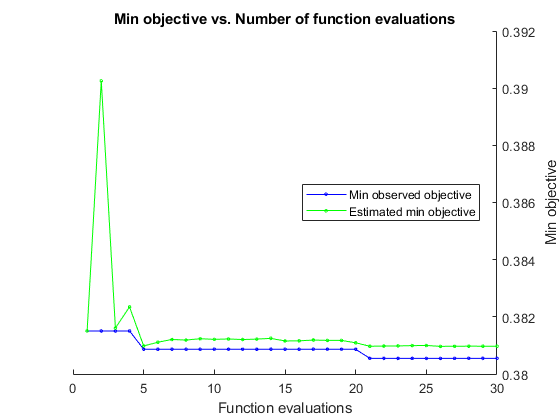

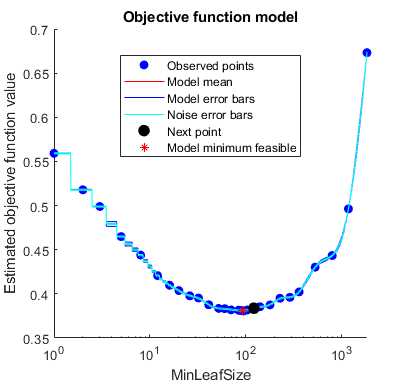


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 41.9941 seconds.
Total objective function evaluation time: 2.7899

Best observed feasible point:
    MinLeafSize
    ___________

        94     

Observed objective function value = 0.38055
Estimated objective function value = 0.38097
Function evaluation time = 0.052445

Best estimated feasible point (according to models):
    MinLeafSize
    ___________

        93     

Estimated objective function value = 0.38097
Estimated function evaluation time = 0.064633



T_opt_auto = fitrtree(x_cart, y_cart,'OptimizeHyperparameters','auto');

y_cart_predict_val = predict(T_opt_auto, x_cart_val);
y_cart_predict_val = [x_val_norm(1); y_cart_predict_val];
x_cart_predict_val = y_cart_predict_val .* sigma_x_val + mean_x_val;
r2_cart_auto_val = r2_performance(x_val, x_cart_predict_val, mean_x_val)

r2_cart_auto_val = 0.5904

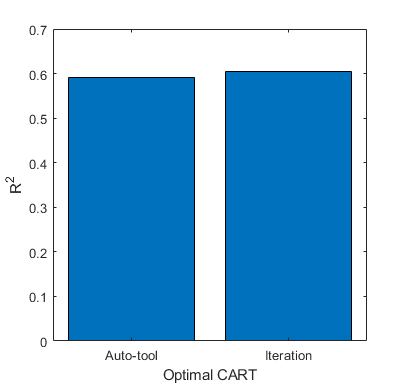

c = categorical({'Iteration','Auto-tool'});
bar(c, [max(r2_cart_val); r2_cart_auto_val])
xlabel('Optimal CART');ylabel('R^2');

## Comparison

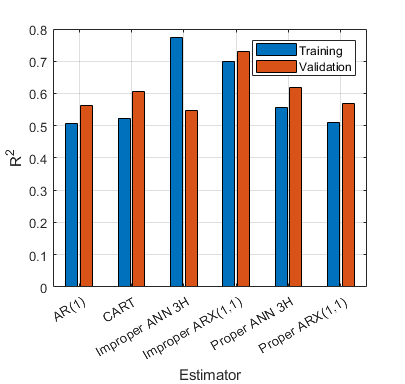

c = categorical({ ...
    'AR(1)', ...
    'Proper ARX(1,1)', ...
    'Improper ARX(1,1)', ...
    'Proper ANN 3H', ...
    'Improper ANN 3H', ...
    'CART', ...
    });
h = bar(c,[ ...
    r2_ar, r2_ar_val; ...
    r2_prop, r2_prop_val; ...
    r2_improp, r2_improp_val; ...
    max(r2_ann_prop), max(r2_ann_prop_val); ...
    max(r2_ann_improp), max(r2_ann_improp_val); ...
    r2_cart(cart_idx), r2_cart_val(cart_idx); ...
    ]);
set(h, {'DisplayName'}, {'Training','Validation'}')
xlabel('Estimator');ylabel('R^2');
legend()
grid on